# Engineering MATLAB: Week 15

**Advanced MATLAB Data Structures**

clear, clc, close all;

## **N-D Arrays**

N-Dimensional arrays are good for holding data in object of a higher dimension than a matrix... we can think of these things as tensors, or a matrix of matrices at the least.

Many common applications of 3D+ arrays are:

- Solving PDEs

- Image Processing (with color)

Solving ODEs and PDEs will be saved for the last lecture of this class, so today we will look at how images are processed in MATLAB. 

% import the image
flower_img_rbg = imread('Molly_006-2829x1886-2726x1886-1920x1328.jpg');

% print out the size of this image using the size() function
size(flower_img_rbg)

ans =         1328        1920           3


What do we notice about this? We should expect to get a 255 x 255 x 3 matrix. This is a 3D array.

What do you think the third entry represents? We can plot this to see:

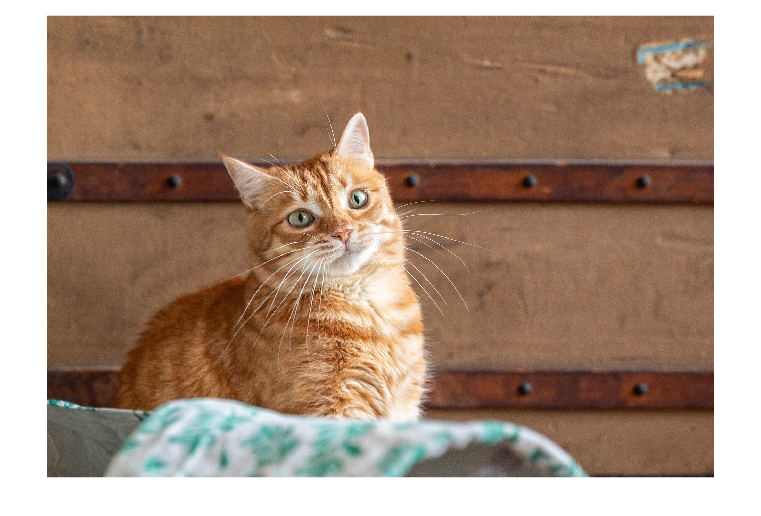

R = flower_img_rbg(:,:,1);
G = flower_img_rbg(:,:,2);
B = flower_img_rbg(:,:,3);

allBlack = zeros(size(flower_img_rbg,1,2),class(flower_img_rbg));
justR = cat(3,R,allBlack,allBlack); % this is a new 3D array of only values in the red channel
justG = cat(3,allBlack,G,allBlack); % this is a new 3D array with only non-zero valeus in green
justB = cat(3,allBlack,allBlack,B); 
figure
imshow(flower_img_rbg)

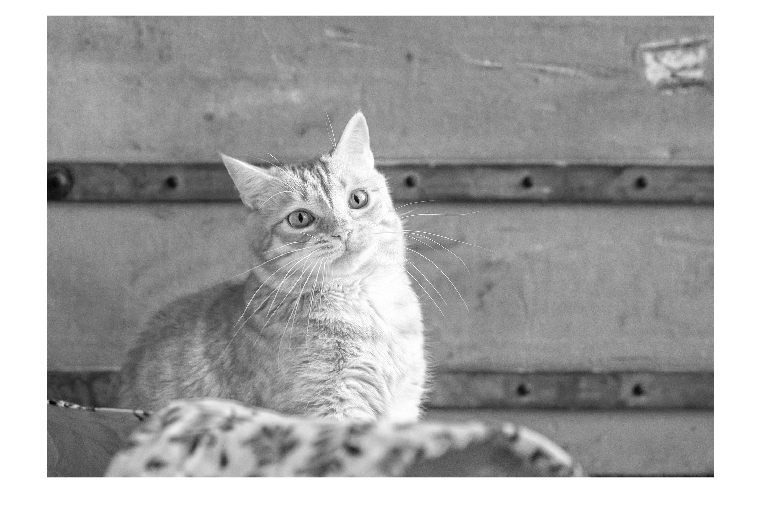

imshow(B)
hold on;
imshow(R)


allBlack

allBlack = 1328×1920 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

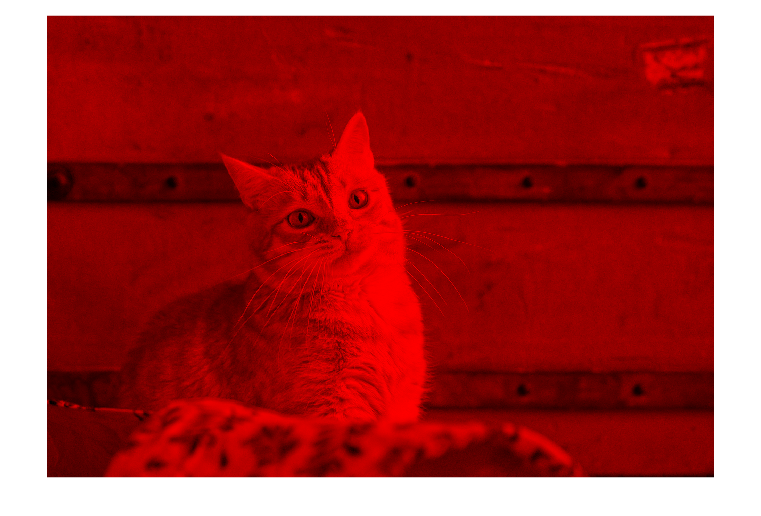

figure
imshow(justR)

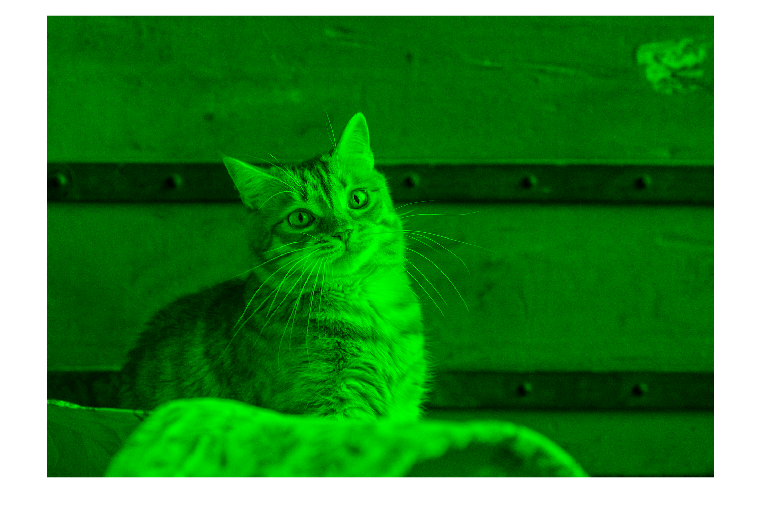

figure
imshow(justG)

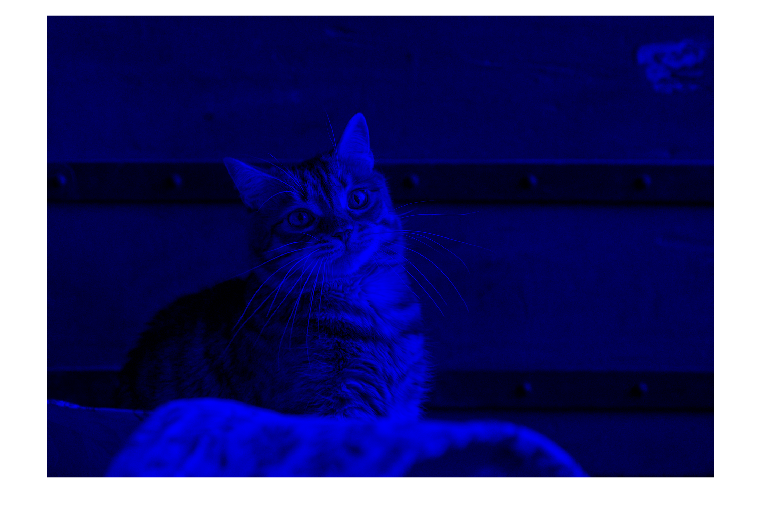

figure
imshow(justB)

Think about what I have done here. You do not need to know what the commands cat() does, but part of your assignment for today should be to determine what happened and how I displayed these. 

## **Cell Arrays**

Cell arrays are a type of data structure where each element can be any type of data. We start these data structures with the commands:

cellarr1 = {500, rand([200,200]), ['Hello', 'World'], flower_img_rbg}

cellarr1 = 1×4 cell array
    {[500]}    {200×200 double}    {'HelloWorld'}    {1328×1920×3 uint8}


imshow(cellarr1{4})

cellarr1{2}

ans =     0.4405    0.5877    0.1476    0.2023    0.5340    0.4701    0.1260    0.6765    0.7832    0.8035    0.7885    0.5602    0.2172    0.7581    0.7665    0.3523    0.5170    0.7287    0.8410    0.5491    0.2255    0.0885    0.7610    0.1622    0.8809    0.3368    0.5693    0.0073    0.2369    0.6457    0.5570    0.6096    0.4975    0.8984    0.7138    0.4753    0.6138    0.9109    0.1838    0.9471    0.5254    0.0965    0.6304    0.4030    0.7039    0.3208    0.1005    0.2469    0.6574    0.4958
    0.3680    0.8644    0.4832    0.3995    0.1555    0.0039    0.9680    0.2678    0.5024    0.0928    0.0017    0.3734    0.0605    0.2590    0.0467    0.9160    0.3208    0.3330    0.8757    0.3475    0.2275    0.8335    0.7569    0.3893    0.3327    0.4798    0.8169    0.6984    0.3674    0.5141    0.9004    0.4140    0.9224    0.5712    0.1838    0.0913    0.0454    0.9259    0.9935    0.2672    0.3611    0.2331    0.1153    0.2302    0.1062    0.1615    0.2910    0.4808    0.1714   

I have seen cell arrays professionally a lot in the aerospace field where using a type of filter, called the Kalman Filter, stores each of the updated iterations inside of a cell array. This can be messy, so this may not always be the right solution. As you will find out in programming, many solutions give you the same answer in the end. It just depends on what you are comfortable with and the speed of the data structure.

Lets practice doing some sort of computation with cell arrays. In this example, we will learn something called **Markov Chains**. These are computations of probabilistic events using matrices to cover state transitions from one state to another based on a probability of occurance. Lets store each step of this computation as an element in a cell array.

**Problem Statement:**

On the Island of Hope, the weather each day is classified as sunny, cloudy or rainy. The next day's weather depends only on todays weather and not on the weather of the previous days. If the present day is sunny, then the next day will be either sunny, cloudy or rainy with probabilities 0.70, 0.10, and 0.20. The transition probabilities for the present day being cloudy is 0.50, 0.25, 0.25, and the transition probabilities when the present day is raining is 0.40, 0.30, 0.30. What is the probability that it will be sunny three days from now if its raining today?

**Solution:**

We can structure the matrix in this particular way:

                    sunny         cloudy         raining

sunny            0.70            0.10            0.20

cloudy           0.50            0.25            0.25

raining           0.40            0.30            0.30

Formalizing this mathematically, we create the matrix


$$P = \left( \matrix{ 0.70 & 0.10 & 0.20 \cr 0.50 & 0.25 & 0.25 \cr 0.40 & 0.30 & 0.30} \right)$$


The probability matrix N days from now is going to be represented as $P^N$, and to look at our particular probability in question we look at the row that corresponds to our initial day and then the column of our target result. Thus, for the probability to be sunny three days from now if it is raining today, we look at


$$P_{sunny, 3 days} = [P^{N}]_{3,1}$$
 

where (3,1) represents third row, first column.

In code,

P = [0.70, 0.10, 0.20; 0.50, 0.25, 0.25; 0.40, 0.30, 0.30]

P =     0.7000    0.1000    0.2000
    0.5000    0.2500    0.2500
    0.4000    0.3000    0.3000


Now using a cell array we can calculate the computation per every day

P_days{1} = P;
for days = 2:3
    P_days{days} = P_days{days - 1} * P;
end

p_day3_sunny_ifrained = P_days{3}(3,1)

p_day3_sunny_ifrained = 0.5855

How about 7 days from now?

for days = 2:7
    P_days{days} = P_days{days - 1} * P;
end

p_day7_sunny_ifRained = P_days{7}(3,1)

p_day7_sunny_ifRained = 0.5960

12 days?

for days = 2:12
    P_days{days} = P_days{days - 1} * P;
end

p_day12_sunny_ifRained = P_days{12}(3,1)

p_day12_sunny_ifRained = 0.5960

P_days{12}

ans =     0.5960    0.1722    0.2318
    0.5960    0.1722    0.2318
    0.5960    0.1722    0.2318


P_days{4}(3,2)

ans = 0.1739

for days = 2 : 4
    P_days{days} = P_days{days - 1}*P;
end
P_days{4}(3,2)

ans = 0.1739

## **Tables**

Working with an advanced Housing Market dataset, lets read this in as a table and see how easy this becomes:

HousingData = readtable('advanced_housing.csv', 'VariableNamingRule', 'preserve')

HousingData = 1460×81 table
    Id    MSSubClass    MSZoning    LotFrontage    LotArea     Street     Alley     LotShape    LandContour    Utilities     LotConfig     LandSlope    Neighborhood    Condition1    Condition2     BldgType     HouseStyle    OverallQual    OverallCond    YearBuilt    YearRemodAdd    RoofStyle     RoofMatl      Exterior1st    Exterior2nd    MasVnrType     MasVnrArea    ExterQual    ExterCond    Foundation    BsmtQual    BsmtCond

This will be a little easier to handle because we do not need to focus on which index in the array holds a value. We can call the table by the column name:

HousingData(:, 'YrSold')

ans = 1460×1 table
    YrSold
    ______

     2008 
     2007 
     2008 
     2006 
     2008 
     2009 
     2007 
     2009 
     2008 
     2008 
     2008 
     2006 
     2008 
     2007 
     2008 
     2007 


HousingData.YrSold

ans =         2008
        2007
        2008
        2006
        2008
        2009
        2007
        2009
        2008
        2008


Lets plot the sale amount vs the year sold

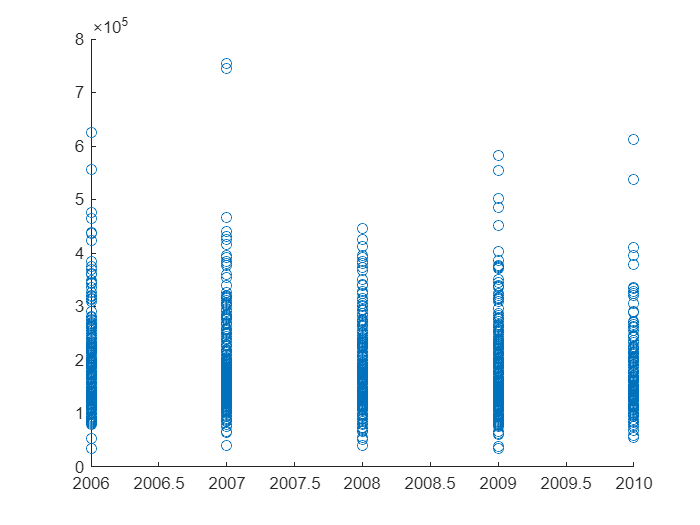

figure()
scatter(HousingData.YrSold, HousingData.SalePrice)

## **Structures**

Structures will be our first data structure that is similar to something you would see in C/C++. These are objects that can contain as many fields as you like. For our example, we will do some projectile motion with drag problems.

Lets create two objects with different mass properties:

dillon.age = 32;
dillon.education = "masters"

dillon = struct with fields:
          age: 32
    education: "masters"


dillon

dillon = struct with fields:
          age: 32
    education: "masters"




obj1.mass = 10; % 10 kg
obj2.mass = 10; % 10 kg

% lets look at obj1
obj1

obj1 = struct with fields:
    mass: 10


Note how this data is "struct with fields". Structures allow us to make data types with fields inside of them that we can create/access with the "." operator. Lets add some other features that may be similar to designing a simulator in MATLAB:

% simulation parameters
simparams.density = 1.2;
simparams.angle = 45;
simparams.gravity = 9.81;
simparams.run_time = 10;
simparams.dt = 0.01;

simparams

simparams = struct with fields:
     density: 1.2000
       angle: 45
     gravity: 9.8100
    run_time: 10
          dt: 0.0100



% object parameters
obj1.cd = 0.01;
obj1.v0 = 50;
obj1

obj1 = struct with fields:
    mass: 10
      cd: 0.0100
      v0: 50



obj2.cd = 0.05;
obj2.v0 = 50;

Now that we have set up the simulation that calculates these values:

[obj1.x, obj1.y, obj1.vx, obj1.vy] = ProjectileSimulator(obj1, simparams);
[obj2.x, obj2.y, obj2.vx, obj2.vy] = ProjectileSimulator(obj2, simparams);

Now we can visualize these results:

obj1

obj1 = struct with fields:
    mass: 10
      cd: 0.0100
      v0: 50
       x: [0.3534 0.7066 1.0596 1.4125 1.7651 2.1176 2.4699 2.8221 3.1741 3.5259 3.8775 4.2290 4.5803 4.9314 5.2823 5.6331 5.9837 6.3341 6.6844 7.0345 7.3844 7.7342 8.0838 8.4332 8.7825 9.1316 9.4805 9.8292 10.1778 10.5263 10.8745 … ] (1×685 double)
       y: [0.3524 0.7036 1.0537 1.4026 1.7504 2.0970 2.4425 2.7868 3.1300 3.4720 3.8129 4.1526 4.4912 4.8286 5.1649 5.5000 5.8340 6.1669 6.4986 6.8291 7.1586 7.4868 7.8140 8.1400 8.4649 8.7886 9.1112 9.4327 9.7530 10.0722 10.3903 … ] (1×685 double)
      vx: [35.3553 35.3377 35.3200 35.3024 35.2849 35.2674 35.2499 35.2325 35.2151 35.1977 35.1804 35.1632 35.1460 35.1288 35.1116 35.0945 35.0775 35.0605 35.0435 35.0266 35.0097 34.9928 34.9760 34.9592 34.9425 34.9258 34.9091 34.8925 … ] (1×686 double)
      vy: [35.3553 35.2396 35.1239 35.0083 34.8928 34.7774 34.6620 34.5468 34.4317 34.3166 34.2016 34.0867 33.9719 33.8572 33.7426 33.6281 33.5136 33.3993 33.2850 33.1708 33.056

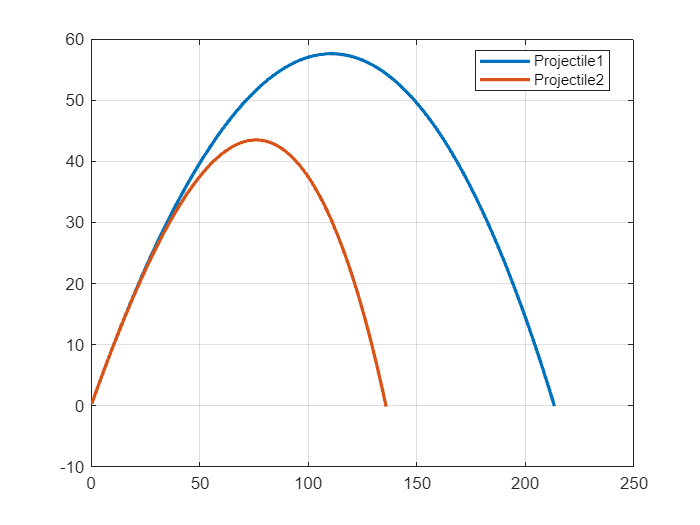

figure()
plot(obj1.x, obj1.y, 'LineWidth', 2)
hold on;
plot(obj2.x, obj2.y, 'LineWidth', 2)
legend('Projectile1', 'Projectile2', 'Location','best')
grid on; box on;
hold off;

## **Problems**

### Problem 1

Describe what the "cat" function does, and talk me through how the justR, justG, and justB matrices work.

### Problem 2

Plot a greyscale image by using this formula to decompress the colors in the images,


$$I = colorImage$$



$$greyscale = 0.3\cdot I_{red} + 0.59 \cdot I_{green} + 0.11 \cdot I_{blue}$$


where $I_{red} = I(:,:,1)$

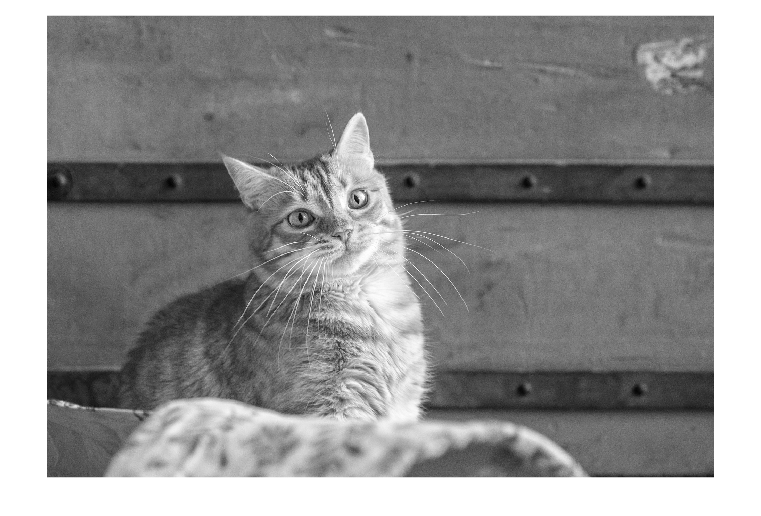

I = imread("Molly_006-2829x1886-2726x1886-1920x1328.jpg");
greyscale = 0.3 * I(:,:,1) + 0.59 * I(:,:,2) + 0.11 * I(:,:,3);
imshow(greyscale)

### Problem 3

Create two new objects, Obj3 and Obj4, and add them to the plot. You have complete flexibility in $C_d$ and $m$.

### Problem 4

Given the transition matrix $P$ in the Markov Chain problem, what is the probability it is sunny 6 days from now given today was cloudy?

### Problem 5

Make a table of size 100 rows and 3+ columns. You can populate these columns with random values (I recommend using some number N*rand()). Then plot a few of these columns versus each other. These graphs don't have to make sense, but it may be more informative to use some formulas to develop the columns. For example, you could make a table where the first column is time, second is position, third is velocty, and fourth is acceleration and plot them all. Use the kinematic formulas to do this.

As an example, to create a table, use the following command:

myTable = table()


myTable =

  0×0 empty table



myTable.time = [0 : 0.1 : 10]';
myTable.t2 = myTable.time.^2;
myTable.t3 = myTable.time.^3;
myTable

myTable = 101×3 table
    time     t2      t3  
    ____    ____    _____

      0        0        0
    0.1     0.01    0.001
    0.2     0.04    0.008
    0.3     0.09    0.027
    0.4     0.16    0.064
    0.5     0.25    0.125
    0.6     0.36    0.216
    0.7     0.49    0.343
    0.8     0.64    0.512
    0.9     0.81    0.729
      1        1        1
    1.1     1.21    1.331
    1.2     1.44    1.728
    1.3     1.69    2.197
    1.4     1.96    2.744
    1.5     2.25    3.375


Now for your example, you can use different mathematical functions (maybe sin/cos/tan?) or physics formulas.

## **Functions**

function [x_pos, y_pos, vx, vy] = ProjectileSimulator(obj, simparams)
    % Initial conditions
    theta  = simparams.angle;
    t_span = simparams.run_time;
    dt     = simparams.dt;
    g      = simparams.gravity;

    t = 0:dt:t_span;

    v0 = obj.v0;
    cd = obj.cd;
    m = obj.mass;

    vx(1) = v0 * cosd(theta); % initial horizontal velocity
    vy(1) = v0 * sind(theta); % initial vertical velocity
    x = 0; % initial x position
    y = 0; % initial y position
    

    
    % Simulation loop
    for i = 1:length(t)
        % Drag force components
        Fdx = -cd * vx(i) * sqrt(vx(i)^2 + vy(i)^2);
        Fdy = -cd * vy(i) * sqrt(vx(i)^2 + vy(i)^2);
    
        % Update velocities (Euler's Method)
        vx(i+1) = vx(i) + (Fdx / m) * dt;
        vy(i+1) = vy(i) + (Fdy / m - g) * dt;

        % Update positions (Euler's Method)
        x = x + vx(i+1) * dt;
        y = y + vy(i+1) * dt;
    
        % Store results
        x_pos(i) = x;
        y_pos(i) = y;
    
        % Stop if projectile hits the ground
        if y < 0
            break;
        end
    end
end